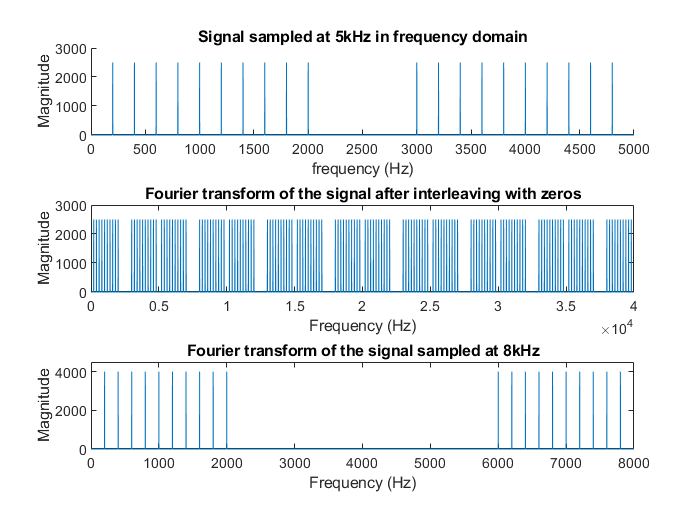

clear all;
close all;
clc;

f = 200; % Signal fundamental frequency of 200Hz.
fs= 5000; % Sampling frequency of 5kHz.
N = 5000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,5000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

signal_supersition = sum(x, 1);
% Plot the orignal signal in time domain.
figure;
subplot(3,1,1);
hold on;
% subplot(2,1,1);
% stem(n, signal_supersition);
% xlabel('n');
% ylabel('x(n)');
% title(['Signal sampled at 5kHz in time domain']);
% soundsc(signal_supersition);
% hold on;
% Plot the original signal in frequency domain.
fft_for_signal = fft(signal_supersition);
f = 0:4999;
% subplot(2,1,2);
plot(f, abs(fft_for_signal));
xlabel('frequency (Hz)');
ylabel('Magnitude');
title('Signal sampled at 5kHz in frequency domain');
ylim([0 3000]);
% hold off;
% Call the function to resample the signal to 8kHz.
Resample_5kHz_to_8kHz(signal_supersition);

function output_signal = Resample_5kHz_to_8kHz(input_signal)
% This function will resample the signal of 5kHz with duration 1 second to
% 8kHz with duration 1 second.

% Since the required sampling frequency after doing up sampling is not a
% integral multiple of the original sampling frequency, we have to firt do
% the up sampling, then do the down sampling. Meaning, first do upsampling by
% 8 times, then down sample by 5 times.
signal_interleave_with_zeros = zeros(1, 40000);
index = 1;
for i = 1:40000
    if mod(i, 8) == 1
        signal_interleave_with_zeros(i) = input_signal(index);
        index = index + 1;
    end
end
fft_for_signal_interleave_with_zeros = fft(signal_interleave_with_zeros);
f = 0:39999;
% figure
subplot(3,1,2);
plot(f, abs(fft_for_signal_interleave_with_zeros));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier transform of the signal after interleaving with zeros');
ylim([0 3000]);
% hold off;
% As we can see in the frequency domain, the transform of the upsampling
% samples are the copies of the original samples, this means that the
% transform of the original samples was "compressed" within (0, 2*pi),
% where 2*pi denotes the sampling frequency, and since we upsample the
% original samples by a factor of 8, from 0 to 2*pi in the frequency
% domain, it contains 8 copies of the original transform. And the transform
% from 0 to 2500Hz will contain all information about the original signal,
% thus, we filter this spectrum up to 2.5kHz.
% We also filter out these frequency components to avoid aliasing.

% Here in order to make sure that after doing inverse transform, we
% still have the same signal amplitude as the signal before doing
% upsampling, we multiply the amplitude of the fourier transform for the
% upsampling signal by a factor of 16.
fft_for_upsampling_after_filtering=  [16*fft_for_signal_interleave_with_zeros(1:2501), zeros(1, 37499)];
% Since for this transfrom we have 0 padding, the inverse transform is of
% complex number, we take the real part of these complex numbers.
signal_after_upsampling = real(ifft(fft_for_upsampling_after_filtering));
% n = 0:39999;
% stem(n, signal_after_upsampling); 

signal_after_downsampling = zeros(1, 8000);
index = 1;
for i = 1:40000
    if mod(i, 5) == 1
        signal_after_downsampling(index) = signal_after_upsampling(i);
        index = index + 1;
    end
end
k = 0:7999;
% figure
subplot(3,1,3)
% subplot(2,1,1);
% stem(k, signal_after_downsampling);
% xlabel('n');
% ylabel('x(n)');
% title('Signal sampled at 8kHz in time domain');
fft_for_signal_after_downsampling_ = fft(signal_after_downsampling);
% subplot(2,1,2);
plot(k, abs(fft_for_signal_after_downsampling_));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier transform of the signal sampled at 8kHz');
ylim([0 4500]);
% soundsc(signal_after_downsampling);
output_signal = signal_after_downsampling;
% soundsc(signal_after_downsampling*10/3.5);

end


